# **Hilbert Transform**

The Hilbert transform is an operation that shifts the phase of every frequency component in a signal by exactly **90°**, without changing the magnitude at any frequency.

In the frequency domain, the Hilbert Transform multiplies:  

- **+  **Positive frequencies by -j  (a -90 degree phase shift)

- **--  **Negative frequencies by +j  (a +90 degree phase shift)

**What it does to sinusoids:**

cos(w0*n)  -->  sin(w0*n)

**In MATLAB, the full analytic signal is computed in one line:**

x_a = hilbert(x);

N  = 80;
n  = 0:N-1;
w0 = 0.2*pi;

x_pos = 0.5 * exp(1j*w0*n);         % positive component
x_neg = 0.5 * exp(-1j*w0*n);        % negative component
x = x_pos + x_neg;                  % cosine signal: x[n] = 0.5 e^{j w0 n} + 0.5 e^{-j w0 n} = cos(w0 n)

% Apply the Hilbert-transform rule in the frequency-domain sense:
% positive frequencies multiply by -j
% negative frequencies multiply by +j
xH_components = (-1j)*x_pos + (1j)*x_neg;

% The result should be a sine (ensure signal is real)
xH_real = real(xH_components);

% For comparison, the expected sine
xH_expected = sin(w0*n);

% Analytic signal formed from x + j*xH_components
xa = x + 1j*xH_components;

% Plot time-domain signals
figure('Color','w');

subplot(3,1,1);
stem(n, real(x), 'filled');
grid on;
xlabel('n');
ylabel('x[n]');
title('Original cosine: $x[n] = 0.5e^{j\omega_0 n} + 0.5e^{-j\omega_0 n}$', 'Interpreter','latex');

subplot(3,1,2);
stem(n, xH_real, 'filled'); hold on;
plot(n, xH_expected, 'r--', 'LineWidth', 1.2);
grid on;
xlabel('n');
ylabel('$\hat{x}[n]$','Interpreter','latex');
title('Hilbert transform built from (-j) on +freq and (+j) on -freq');
legend('Constructed Hilbert transform','Expected sin(w_0 n)','Location','best');

subplot(3,1,3);
stem(n, real(x), 'filled'); hold on;
stem(n, xH_real, 'filled');
grid on;
xlabel('n');
ylabel('Amplitude');
title('Comparison of original cosine and Hilbert transform');
legend('cos(w_0 n)','sin(w_0 n)','Location','best');
% The algebra numerically
disp(max(abs(xH_real - xH_expected)));
% x + j*xH leaves only the positive-frequency phasor
figure('Color','w');
subplot(2,1,1);
stem(n, real(xa), 'filled'); hold on;
stem(n, imag(xa), 'filled');
grid on;
xlabel('n');
ylabel('Amplitude');
title('Analytic signal $x_a[n] = x[n] + j\hat{x}[n]$', 'Interpreter', 'latex');
legend('Real part','Imag part','Location','best');

subplot(2,1,2);
plot(real(xa), imag(xa), 'o-');
axis equal; grid on;
xlabel('Real');
ylabel('Imag');
title('Analytic signal trajectory in complex plane');

## **Envelope and Phase Attraction**

The Hilbert transform lets MATLAB form the **analytic signal**:$x_a[n] = x[n] + j\hat{x}[n]$

where $\hat{x}[n]$ is the Hilbert transform of $x[n]$.

Once you have $x_a[n]$:

- the **envelope** is $|x_a[n]|$

- the **phase** is $\angle\, x_a(t)$

All three are derived from a single call to hilbert(x).

Envelope      — how amplitude varies over time

Phase           — instantaneous angle of the oscillation

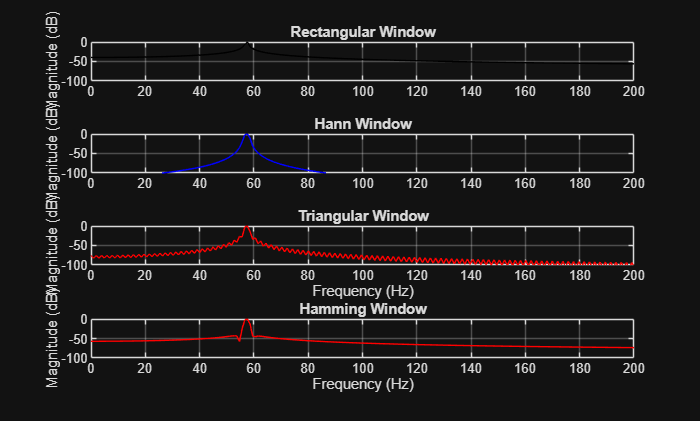

fs = 2000;          % sampling rate 2000 Hz
t = 0:1/fs:1;       % time vector from 0 to 1 second, step = 1/2000
fc = 100;           % carrier frequency 100 Hz
fm = 3;             % modulating frequency 3 Hz

% True envelope ( varied between 0.5 and 1.5 with frequendcy of 3 Hz )
A = 1 + 0.5*cos(2*pi*fm*t);

% AM signal ( Envelope (A) * carrier )
x = A .* cos(2*pi*fc*t);

% Analytic signal (via Matlab hilbert function)
xa = hilbert(x);

% Envelope extraction
env_est = abs(xa);
positive_env = env_est;
negative_env = -env_est;

% Phase extraction
phi = unwrap(angle(xa));

% -------------------------------
% Plot everything
% -------------------------------

figure('Color','w');

% --- Signal ---
subplot(3,1,1);
plot(t, x, 'b');
grid on;
xlabel('Time (s)');
ylabel('x(t)');
title('Amplitude-modulated signal');

% --- Envelope (positive + negative) ---
subplot(3,1,2);
plot(t, x, 'b'); hold on;
plot(t,  positive_env, 'r', 'LineWidth', 1.5);
plot(t, negative_env, 'r', 'LineWidth', 1.5);
plot(t,  A, 'k--', 'LineWidth', 1.2);   % true envelope
plot(t, -A, 'k--', 'LineWidth', 1.2);
grid on;

xlabel('Time (s)');
ylabel('Amplitude');
title('Envelope extraction (upper and lower)');
legend('Signal','+|xa|','-|xa|','True +A','True -A','Location','best');

% --- Phase ---
subplot(3,1,3);
plot(t, phi, 'm', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');
ylabel('Phase (rad)');
title('Unwrapped phase from analytic signal');

## **Repeat for the chirp signal**

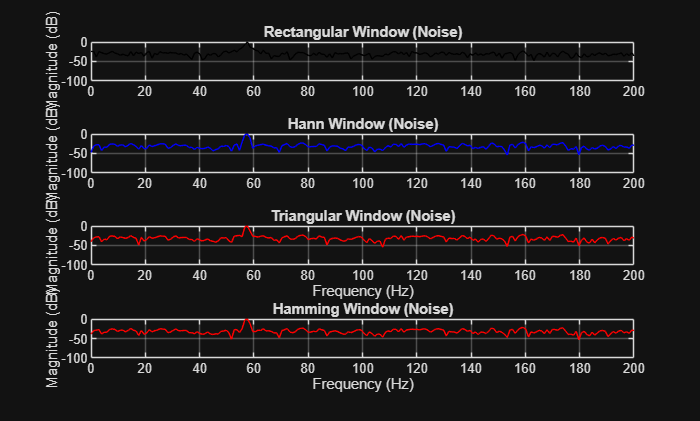

fs = 2000;       % sampling rate 2000 Hz
t = 0:1/fs:1;    % 1 second of time, 2001 samples

% Slowly varying envelope ( varied between 0.6 and 1.4 with frequendcy of 2 Hz )
A = 1 + 0.4*cos(2*pi*2*t);

% Chirp phase (frequency increases over time), carrier frequency

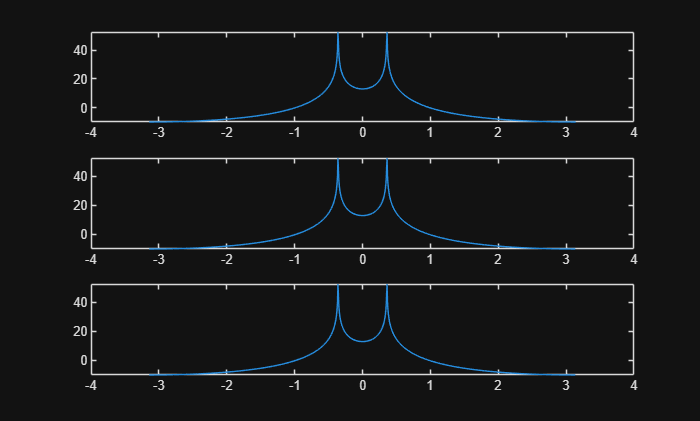

phi_true = 2*pi*(50*t + 60*t.^2);

% Signal ( Envelope (A) * carrier )
x = A .* cos(phi_true);

% Analytic signal
xa = hilbert(x);

% Envelope and phase
env_est = abs(xa);
phi_est = unwrap(angle(xa));

% -------------------------------
% Plot
% -------------------------------
figure('Color','w');

% --- Signal ---
subplot(3,1,1);
plot(t, x, 'b');
grid on;
xlabel('Time (s)');
ylabel('x(t)');
title('AM-FM signal (chirp)');

% --- Envelope (positive + negative) ---
subplot(3,1,2);
plot(t, x, 'b'); hold on;

plot(t,  env_est, 'r', 'LineWidth', 1.5);
plot(t, -env_est, 'r', 'LineWidth', 1.5);


plot(t,  A, 'k--', 'LineWidth', 1.2);
plot(t, -A, 'k--', 'LineWidth', 1.2);

grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Envelope extraction (upper and lower)');
legend('Signal','+|xa|','-|xa|','True +A','True -A','Location','best');

% --- Phase ---
subplot(3,1,3);
plot(t, phi_est, 'm', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');
ylabel('Phase (rad)');
title('Unwrapped phase (chirp)');

## **Instantaneous Frequency**

The instantaneous frequency is estimated as the slope of the phase spectrum: $f(t) = \frac{1}{2\pi}\frac{d\phi(\omega)}{dt}$ or in the discrete version $f[n] = \frac{1}{2\pi}\left[\phi[n]-\phi[n-1]\right]\cdot F_S$

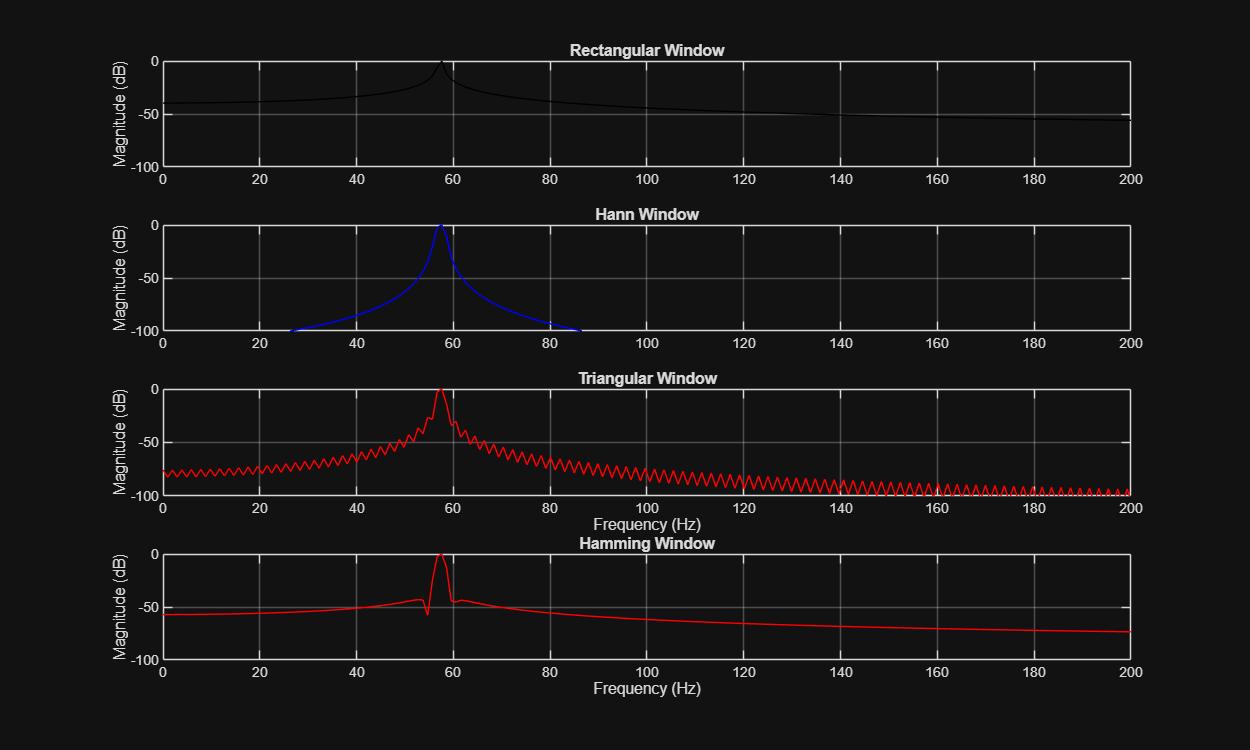

fs = 48000;
t = 0:1/fs:0.03;                 % 30 ms
f0 = 500;                        % start frequency
k  = 30000;                      % chirp rate in Hz/s

A = 1 + 0.3*cos(2*pi*40*t);      % slow envelope
phi_true = 2*pi*(f0*t + 0.5*k*t.^2);
x = A .* cos(phi_true);

xa = hilbert(x);
env_est = abs(xa);
phi_est = unwrap(angle(xa));
% we include a NaN so the length of vectors 
% match for plotting purposes
% Estimate the instantaneous frequency
f_inst = [diff(phi_est) / (2*pi) * fs, NaN];

figure('Color','w');

subplot(4,1,1);
plot(t, x, 'b');
grid on;
xlabel('Time (s)');
ylabel('x(t)');
title('AM-FM signal');

subplot(4,1,2);
plot(t, env_est, 'r', 'LineWidth', 1.2); hold on;
plot(t, -env_est, 'r', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');

ylabel('Envelope');
title('Envelope from analytic signal');


 hamming - Hamming window
    This MATLAB function returns an L-point symmetric Hamming window.

    Syntax
      w = hamming(L)
      w = hamming(L,sflag)

    Input Arguments
      L - Window length
        positive integer
      sflag - Window sampling
        "symmetric" (default) | "periodic"

    Output Arguments
      w - Hamming window
        column vector

    Examples
      Hamming Window
      

subplot(4,1,3);

 hann - Hann (Hanning) window
    This MATLAB function returns an L-point symmetric Hann window.

    Syntax
      w = hann(L)
      w = hann(L,sflag)
      w = hann(___,typeName)

    Input Arguments
      L - Window length
        positive integer
      sflag - Window sampling
        "symmetric" (default) | "periodic"
      typeName - Output data type
        "double" (default) | "single"

    Output Arguments
      <a

plot(t, phi_est, 'm', 'LineWidth', 1.2);

 blackman - Blackman window
    This MATLAB function returns an L-point symmetric Blackman window.

    Syntax
      w = blackman(L)
      w = blackman(L,sflag)
      w = blackman(___,typeName)

    Input Arguments
      L - Window length
        positive integer
      sflag - Window sampling
        "symmetric" (default) | "periodic"
      typeName - Output data type
        "double" (default) | "single"

    Output Arguments
      

grid on;

 kaiser - Kaiser window
    This MATLAB function returns an L-point Kaiser window with shape factor
    beta.

    Syntax
      w = kaiser(L,beta)

    Input Arguments
      L - Window length
        positive integer
      beta - Shape factor
        0.5 (default) | positive real scalar

    Output Arguments
      w - Kaiser window
        column vector

    Examples
      Kaiser Window

    See also Window Designer, 

xlabel('Time (s)');
ylabel('Phase (rad)');
title('Unwrapped instantaneous phase');

subplot(4,1,4);
plot(t, f_inst, 'k', 'LineWidth', 1.2); hold on;
plot(t, f0 + k*t, 'g--', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Instantaneous frequency from phase slope');
legend('Estimated','True','Location','best');
legend('Estimated','True','Location','best');

# **Spectral Analysis with Windows**

### What is it ?

When you compute the FFT of a signal, you are only looking at a **finite chunk** of it. Cutting a signal to a finite length is equivalent to multiplying it by a **rectangular window** — it's abruptly set to zero outside the observed segment. This causes problems in the frequency domain called **spectral leakage**.

### What is a spectral leakage ?

A pure sine wave theoretically has energy at exactly one frequency. But when you window it, the sharp edges of the rectangular cut introduce **side lobes** — energy that spreads into neighbouring frequency bins where there should be none.

---

When signals align closely with **FFT bins**, the differences between window functions may not be obvious — because there's **minimal spectral leakage** to begin with. To make the **effect of windowing clearly visible**, we need to **intentionally create leakage** by designing a signal that does not align perfectly with the FFT bins. This triggers spectral leakage.

function X = dtft(x, n, w)
% Computes the discrete-time Fourier Transform
% X = dtft(x,n,w)
%
% X = DTFT values computed a w frequencies
% x = finite duration sequence over n (row vector)
% n = sample position row vector
% w = frequency row vector
x = x(:).' ;
n = n(:).' ;
w = w(:).' ;
X = x*exp(-j*n.'*w) ;
end

%% Spectral Analysis: Demo of Windowing Effects
clear ; close all ; clc ;

Fs = 1000 ;              % Sampling frequency
N = 1024 ;               % FFT and signal length
t = (0:N-1)/Fs ;         % Time vector

f0 = 57.3 ; 
% Non-bin-aligned frequency to induce leakage
x = sin(2*pi*f0*t) ;     % Single sinusoid with leakage

% Adding noise to the signal (Uncomment below)
x_noise = x + 0.4*randn(size(x));     % Add noise to the signal (0.4 varied)

## Window Definitions (4 types)

Rectangular $R_{M}[n] = \left\{\begin{array}{ll}
                          1\, \text{,} & 0 \le n < M \\
                          0\, \text{,} & \text{otherwise}                         
\end{array}$

Hanning $C_{M}[n] = 0.5\left[1 - \cos\left(\frac{2\,\pi\,n}{M-1}\right)\right]R_{M}[n]$

Triangular $T_{M}[n] = \left[1- \frac{|M-1-2\,n|}{M-1}\right]R_{M}[n]$

Hamming $H_{M}[n] = \left[0.54 - 0.46\cos\left(\frac{2\,\pi\,n}{M-1}\right)\right]R_{M}[n]$

M = 1024; % Same value as N in the previous code for x with N samples of 1024
n = 0:M-1;

w_rect    = ones(1, M);                                    % R_M[n] = 1 for 0 <= n < M

w_hann    = 0.5 * (1 - cos(2*pi*n / (M-1))) .* w_rect;   % C_M[n]

w_tri     = (1 - abs(M-1-2*n) / (M-1)) .* w_rect;        % T_M[n]

w_hamming = (0.54 - 0.46*cos(2*pi*n / (M-1))) .* w_rect; % H_M[n]

% Apply windows to the signal x
x_rect    = x .* w_rect;
x_hann    = x .* w_hann;
x_tri     = x .* w_tri;
x_hamming = x .* w_hamming;

% Apply windows to the signal x_noise
x_rect_noise    = x_noise .* w_rect;
x_hann_noise    = x_noise .* w_hann;
x_tri_noise     = x_noise .* w_tri;
x_hamming_noise = x_noise .* w_hamming;

## Plot the One-Sided Spectrum Using the DTFT

% DTFT - original signal
xn = (0:N-1);
w = pi*(-1:1/(N/2):1);
Xr  = abs(dtft(x_rect,    xn, w));
Xh  = abs(dtft(x_hann,    xn, w));
Xt  = abs(dtft(x_tri,     xn, w));
Xhm = abs(dtft(x_hamming, xn, w));

% Normalize and extract one-sided spectrum
Xr  = Xr(N/2+1:end)  / max(Xr);
Xh  = Xh(N/2+1:end)  / max(Xh);
Xt  = Xt(N/2+1:end)  / max(Xt);
Xhm = Xhm(N/2+1:end) / max(Xhm);
fdtft = Fs*w(N/2+1:end)/(2*pi);

% DTFT - noisy signal
Xr_noise  = abs(dtft(x_rect_noise,    xn, w));
Xh_noise  = abs(dtft(x_hann_noise,    xn, w));
Xt_noise  = abs(dtft(x_tri_noise,     xn, w));
Xhm_noise = abs(dtft(x_hamming_noise, xn, w));

% Normalize and extract one-sided spectrum
Xr_noise  = Xr_noise(N/2+1:end)  / max(Xr_noise);
Xh_noise  = Xh_noise(N/2+1:end)  / max(Xh_noise);
Xt_noise  = Xt_noise(N/2+1:end)  / max(Xt_noise);
Xhm_noise = Xhm_noise(N/2+1:end) / max(Xhm_noise);

% Plot original signal
figure
subplot(4,1,1)
plot(fdtft, 20*log10(Xr),  'k'); grid on;
title('Rectangular Window'); ylabel('Magnitude (dB)');
xlim([0 200]); ylim([-100 0]);
subplot(4,1,2)
plot(fdtft, 20*log10(Xh),  'b'); grid on;
title('Hann Window'); ylabel('Magnitude (dB)');
xlim([0 200]); ylim([-100 0]);
subplot(4,1,3)
plot(fdtft, 20*log10(Xt),  'r'); grid on;
title('Triangular Window'); ylabel('Magnitude (dB)');
xlabel('Frequency (Hz)'); xlim([0 200]); ylim([-100 0]);
subplot(4,1,4)
plot(fdtft, 20*log10(Xhm), 'r'); grid on;
title('Hamming Window'); ylabel('Magnitude (dB)');
xlabel('Frequency (Hz)'); xlim([0 200]); ylim([-100 0]);

% Plot noisy signal
figure
subplot(4,1,1)
plot(fdtft, 20*log10(Xr_noise),  'k'); grid on;
title('Rectangular Window (Noise)'); ylabel('Magnitude (dB)');
xlim([0 200]); ylim([-100 0]);
subplot(4,1,2)
plot(fdtft, 20*log10(Xh_noise),  'b'); grid on;
title('Hann Window (Noise)'); ylabel('Magnitude (dB)');
xlim([0 200]); ylim([-100 0]);
subplot(4,1,3)
plot(fdtft, 20*log10(Xt_noise),  'r'); grid on;
title('Triangular Window (Noise)'); ylabel('Magnitude (dB)');
xlabel('Frequency (Hz)'); xlim([0 200]); ylim([-100 0]);
subplot(4,1,4)
plot(fdtft, 20*log10(Xhm_noise), 'r'); grid on;
title('Hamming Window (Noise)'); ylabel('Magnitude (dB)');
xlabel('Frequency (Hz)'); xlim([0 200]); ylim([-100 0]);

## **Using FFT for the DTFT**

We can use the FFT to approximate the DTFT.

First, create our signal.

% --- SIGNAL SETUP ---

Fs = 1000;          % 1000 Hz sampling rate
N  = 1024;          % signal length AND FFT size
t  = (0:N-1)/Fs;    % time vector: 0 to 1.023 seconds
f0 = 57.3;          % NOT a bin-aligned frequency
x  = sin(2*pi*f0*t);

% --- True DTFT ---

w     = pi*(-1:1/(N/2):1);    % 1025 points from -π to +π
Xdtft = abs(dtft(x, xn, w));  % continuous-style DTFT, 1025 pts

% --- DTFT from FFT ---

xfft = fftshift(fft(x, N));   % fftshift function

% --- DTFT evaluated at FFT frequencies ---

Xdtft_from_fft = dtft(x, 0:N-1, w(1:end-1));

**PLOTS**

figure
subplot(3,1,1)
plot(w, 20*log10(abs(Xdtft))) ;
subplot(3,1,2)
plot(w(1:end-1), 20*log10(abs(xfft))) ;
subplot(3,1,3)
plot(w(1:end-1), 20*log10(abs(Xdtft_from_fft))) ;

## Plot the One-Sided Spectrum Using the FFT

Okay, let's do it again using the FFT

Study the code below carefully to see how it is don using the FFT

% FFT
% rectangular windowed signal
Xr  = abs(fft(x_rect, N));
% hanning windowed signal
Xh  = abs(fft(x_hann, N));
% triangular windowed signal
Xt  = abs(fft(x_tri, N));
% hamming windowed signal
Xhm = abs(fft(x_hamming, N));

% Normalize and extract one-sided spectrum
Xr  = Xr(1:N/2+1)  / max(Xr);
Xh  = Xh(1:N/2+1)  / max(Xh);
Xt  = Xt(1:N/2+1)  / max(Xt);
Xhm = Xhm(1:N/2+1) / max(Xhm);
f = Fs*(0:(N/2))/N;



% Plot
figure('Position', [100 100 1000 600]);

subplot(4,1,1)
plot(f, 20*log10(Xr), 'k'); grid on;
title('Rectangular Window'); ylabel('Magnitude (dB)');
xlim([0 200]); ylim([-100 0]);

subplot(4,1,2)
plot(f, 20*log10(Xh), 'b'); grid on;
title('Hann Window'); ylabel('Magnitude (dB)');
xlim([0 200]); ylim([-100 0]);

subplot(4,1,3)
plot(f, 20*log10(Xt), 'r'); grid on;
title('Triangular Window'); ylabel('Magnitude (dB)');
xlabel('Frequency (Hz)');
xlim([0 200]); ylim([-100 0]);

subplot(4,1,4)
plot(f, 20*log10(Xhm), 'r'); grid on;
title('Hamming Window'); ylabel('Magnitude (dB)');
xlabel('Frequency (Hz)');
xlim([0 200]); ylim([-100 0]);

## **Explore Matlab Windowing Functions**

help hamming
help hann
help blackman
help kaiser

## Convolution as a Matrix-Vector Operation

When sequences x[n] and h[n] are of finite duration, then their linear convolution y[n] = x[n] * h[n] can be implemented using matrix-vector multiplication. In this case, we let y[n] and x[n] be column vectors and we have:


$$y = \mathbf{H}\,x$$


where linear shifts in h[n-k] are arranged as rows in the matrix **H**. The matrix **H** has an interesting structure and is called a Toeplitz matrix.

To investigate these issues do the following:

- Let x[n] = {1,2,3,4,5} for n = {0,1,2,3,4} and h[n] = {6,7,8,9} for n = {0,1,2,3}. Determine the linear convolution, y[n], of these two sequences. You can use the conv_m function.

- Express x[n] as a column vector; y[n] as a column vector. Determine the matrix **H**..

- Characterize the matrix **H**.

- Describe the first column and first row of **H**.

- Complete the MATLAB function conv_tp.m Use the MATLAB function toeplitz.